% Center of Mass Calculator and Visualizer

clear
clc

format rat;
syms z r theta x y rho phi;

% User Input
coordSystem = input(['Select a coordinate system. Type and enter in the command prompt "c", "y" or "s" \n ' ...
'c = cartesian, y = cylindrical, s = spherical: '], 's');

if lower(coordSystem) == 'y'
disp("Cylindrical selected");
dens = str2sym(input("Enter your density function in terms of z, r, and/or theta: ", 's'));
disp("For visualization, make sure that:");
disp("z bounds can depend on r and theta, r bounds on theta, and that theta bounds must be constant.");
zLower = str2sym(input('Enter Lower Bound for z: ', 's'));
zUpper = str2sym(input('Enter Upper Bound for z: ', 's'));
rLower = str2sym(input('Enter Lower Bound for r: ', 's'));
rUpper = str2sym(input('Enter Upper Bound for r: ', 's'));
thetaLower = str2sym(input('Enter Lower Bound for theta: ', 's'));
thetaUpper = str2sym(input('Enter Upper Bound for theta: ', 's'));

jacobian = r;
m = int(int(int(jacobian*dens, z, zLower, zUpper), r, rLower, rUpper), theta, thetaLower, thetaUpper);
Myz = int(int(int((r*cos(theta)) * jacobian*dens, z, zLower, zUpper), r, rLower, rUpper), theta, thetaLower, thetaUpper);
Mxz = int(int(int((r*sin(theta)) * jacobian*dens, z, zLower, zUpper), r, rLower, rUpper), theta, thetaLower, thetaUpper);
Mxy = int(int(int(z * jacobian*dens, z, zLower, zUpper), r, rLower, rUpper), theta, thetaLower, thetaUpper);

elseif lower(coordSystem) == 'c'

disp("Cartesian selected");
dens = str2sym(input("Enter your density function in terms of x, y, and/or z: ", 's'));
disp("For visualization, make sure that:");
disp("z bounds can depend on x and y, y bounds on x, and that x bounds must be constant.");
zLower = str2sym(input('Enter Lower Bound for z: ', 's'));
zUpper = str2sym(input('Enter Upper Bound for z: ', 's'));
yLower = str2sym(input('Enter Lower Bound for y: ', 's'));
yUpper = str2sym(input('Enter Upper Bound for y: ', 's'));
xLower = str2sym(input('Enter Lower Bound for x: ', 's'));
xUpper = str2sym(input('Enter Upper Bound for x: ', 's'));

jacobian = 1;
m = int(int(int(jacobian*dens, z, zLower, zUpper), y, yLower, yUpper), x, xLower, xUpper);
Myz = int(int(int(x * jacobian*dens, z, zLower, zUpper), y, yLower, yUpper), x, xLower, xUpper);
Mxz = int(int(int(y * jacobian*dens, z, zLower, zUpper), y, yLower, yUpper), x, xLower, xUpper);
Mxy = int(int(int(z * jacobian*dens, z, zLower, zUpper), y, yLower, yUpper), x, xLower, xUpper);

elseif lower(coordSystem) == 's'

disp("Spherical selected");
dens = str2sym(input("Enter your density function in terms of rho, phi, and/or theta: ", 's'));
disp("For visualization, make sure that:");
disp("rho bounds can depend on phi and theta, phi bounds on theta, and theta bounds must be constant.");
rhoLower = str2sym(input('Enter Lower Bound for rho: ', 's'));
rhoUpper = str2sym(input('Enter Upper Bound for rho: ', 's'));
phiLower = str2sym(input('Enter Lower Bound for phi: ', 's'));
phiUpper = str2sym(input('Enter Upper Bound for phi: ', 's'));
thetaLower = str2sym(input('Enter Lower Bound for theta: ', 's'));
thetaUpper = str2sym(input('Enter Upper Bound for theta: ', 's'));

jacobian = (rho^2)*sin(phi);
m = int(int(int(jacobian*dens, rho, rhoLower, rhoUpper), phi, phiLower, phiUpper), theta, thetaLower, thetaUpper);
Myz = int(int(int((rho*sin(phi)*cos(theta)) * jacobian*dens, rho, rhoLower, rhoUpper), phi, phiLower, phiUpper), theta, thetaLower, thetaUpper);
Mxz = int(int(int((rho*sin(phi)*sin(theta)) * jacobian*dens, rho, rhoLower, rhoUpper), phi, phiLower, phiUpper), theta, thetaLower, thetaUpper);
Mxy = int(int(int((rho*cos(phi)) * jacobian*dens, rho, rhoLower, rhoUpper), phi, phiLower, phiUpper), theta, thetaLower, thetaUpper);
else

error("Invalid selection. Run the script again and enter 'c', 'y', or 's'.");

end

Cartesian selected


For visualization, make sure that:


z bounds can depend on x and y, y bounds on x, and that x bounds must be constant.



% Calculation and Results

xbar = Myz/m;
ybar = Mxz/m;
zbar = Mxy/m;

fprintf('\n--- Calculation Results ---\n');


--- Calculation Results ---


fprintf('Mass (m): %s\n', string(m));

Mass (m): 625/24


fprintf('Center of Mass (x̄, ȳ, z̄): (%s, %s, %s)\n\n', string(xbar), string(ybar), string(zbar));

Center of Mass (x̄, ȳ, z̄): (4, 3, 2)





% Visual Component

disp('Visualizing...')

Visualizing...


To create a plot, please define a numerical bounding box.


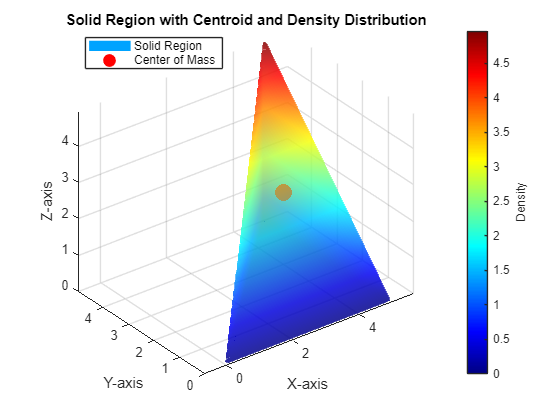


try
plotRes = 150;  % Higher resolution = smoother shapes

disp('To create a plot, please define a numerical bounding box.');
xStr = input('Enter plot range for X as "min max" (e.g., -5 5) and make sure the bounds engulf your entire shape: ', 's');
xVals = str2double(strsplit(xStr));
xRange = [min(xVals), max(xVals)];

yStr = input('Enter plot range for Y as "min max" (e.g., -5 5) and make sure the bounds engulf your entire shape: ', 's');
yVals = str2double(strsplit(yStr));
yRange = [min(yVals), max(yVals)];

zStr = input('Enter plot range for Z as "min max" (e.g., -5 5) and make sure the bounds engulf your entire shape: ', 's');
zVals = str2double(strsplit(zStr));
zRange = [min(zVals), max(zVals)];

[X, Y, Z] = ndgrid(linspace(xRange(1), xRange(2), plotRes), linspace(yRange(1), yRange(2), plotRes), linspace(zRange(1), zRange(2), plotRes));

isInside = false(size(X));

if lower(coordSystem) == 'y' % Cylindrical
R = sqrt(X.^2 + Y.^2);
THETA = mod(atan2(Y, X), 2*pi);  % Map to [0, 2π)
if isempty(symvar(zLower)), zL_fun = @(varargin) double(zLower); else, zL_fun = matlabFunction(zLower, 'Vars', {r, theta}); end
if isempty(symvar(zUpper)), zU_fun = @(varargin) double(zUpper); else, zU_fun = matlabFunction(zUpper, 'Vars', {r, theta}); end
if isempty(symvar(rLower)), rL_fun = @(varargin) double(rLower); else, rL_fun = matlabFunction(rLower, 'Vars', {theta}); end
if isempty(symvar(rUpper)), rU_fun = @(varargin) double(rUpper); else, rU_fun = matlabFunction(rUpper, 'Vars', {theta}); end
isInside = (Z >= zL_fun(R, THETA)) & (Z <= zU_fun(R, THETA)) & (R >= rL_fun(THETA)) & (R <= rU_fun(THETA)) & (THETA >= double(thetaLower)) & (THETA <= double(thetaUpper));

elseif lower(coordSystem) == 'c' % Cartesian
if isempty(symvar(zLower)), zL_fun = @(varargin) double(zLower); else, zL_fun = matlabFunction(zLower, 'Vars', {x, y}); end
if isempty(symvar(zUpper)), zU_fun = @(varargin) double(zUpper); else, zU_fun = matlabFunction(zUpper, 'Vars', {x, y}); end
if isempty(symvar(yLower)), yL_fun = @(varargin) double(yLower); else, yL_fun = matlabFunction(yLower, 'Vars', {x}); end
if isempty(symvar(yUpper)), yU_fun = @(varargin) double(yUpper); else, yU_fun = matlabFunction(yUpper, 'Vars', {x}); end

isInside = (Z >= zL_fun(X, Y)) & (Z <= zU_fun(X, Y)) & (Y >= yL_fun(X)) & (Y <= yU_fun(X)) & (X >= double(xLower)) & (X <= double(xUpper));

elseif lower(coordSystem) == 's' % Spherical
RHOgrid = sqrt(X.^2 + Y.^2 + Z.^2);
PHIgrid = acos(Z ./ RHOgrid);
THETAgrid = mod(atan2(Y, X), 2*pi);  % Ensure [0, 2π)
if isempty(symvar(rhoLower)), rhoL_fun = @(varargin) double(rhoLower); else, rhoL_fun = matlabFunction(rhoLower, 'Vars', {phi, theta}); end
if isempty(symvar(rhoUpper)), rhoU_fun = @(varargin) double(rhoUpper); else, rhoU_fun = matlabFunction(rhoUpper, 'Vars', {phi, theta}); end
if isempty(symvar(phiLower)), phiL_fun = @(varargin) double(phiLower); else, phiL_fun = matlabFunction(phiLower, 'Vars', {theta}); end
if isempty(symvar(phiUpper)), phiU_fun = @(varargin) double(phiUpper); else, phiU_fun = matlabFunction(phiUpper, 'Vars', {theta}); end

isInside = (RHOgrid >= rhoL_fun(PHIgrid, THETAgrid)) & (RHOgrid <= rhoU_fun(PHIgrid, THETAgrid)) & (PHIgrid >= phiL_fun(THETAgrid)) & (PHIgrid <= phiU_fun(THETAgrid)) & (THETAgrid >= double(thetaLower)) & (THETAgrid <= double(thetaUpper));
end

if ~any(isInside(:))
error('The specified solid does not exist within the provided plot range.');
end

figure;
hold on;
fv = isosurface(X, Y, Z, isInside, 0.5);

vars = symvar(dens);
densCartesian = dens;
if any(ismember(vars, [r, theta]))
densCartesian = subs(densCartesian, {r, theta}, {sqrt(x^2+y^2), atan2(y,x)});
end
if any(ismember(vars, [rho, phi]))
densCartesian = subs(densCartesian, {rho, phi, theta}, ...
{sqrt(x^2+y^2+z^2), acos(z/sqrt(x^2+y^2+z^2)), atan2(y,x)});
end

densFunCart = matlabFunction(densCartesian, 'Vars', {x, y, z});
colorData = densFunCart(fv.vertices(:,1), fv.vertices(:,2), fv.vertices(:,3));

if isscalar(colorData)
    colorData = repmat(colorData, size(fv.vertices,1), 1);
end

p = patch('Vertices', fv.vertices, 'Faces', fv.faces, ...
'FaceVertexCData', colorData, ...
'FaceColor', 'interp', ...
'EdgeColor', 'none', ...
'FaceAlpha', 0.6);

plot3(double(xbar), double(ybar), double(zbar), 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');

title('Solid Region with Centroid and Density Distribution');
xlabel('X-axis'); ylabel('Y-axis'); zlabel('Z-axis');
legend({'Solid Region', 'Center of Mass'}, 'Location', 'best');
axis equal; grid on; view(3); rotate3d on;
colormap jet; 
cb = colorbar;                  
cb.Label.String = 'Density';
hold off
rotate3d on

catch ME
fprintf('\n--- Visualization Failed ---\n');
disp('The solid could not be plotted. This can happen if:')
disp('- The specified bounds do not form a closed region.');
disp('- The plot range does not contain the solid.');
disp('- An input was not a valid symbolic expression.');
disp('The calculation results shown above are still correct.');
disp('Error message:');
disp(ME.message);
end